Author: Dylan Lozon

Class: ECE 101

Assignment: MATLAB Final

Date: May 16 2023 

Purpose: This code simulates a simple house fan using a Finite State Machine. (Pictured Below)

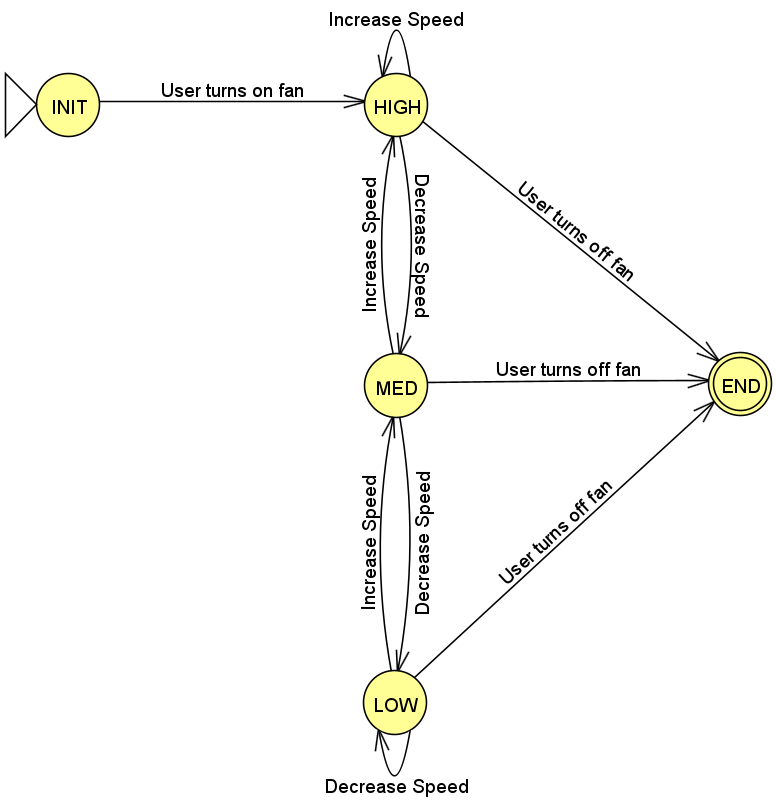

## Prepare workspace

clc
clear

% Initialize variables
currentState = FanState.INIT;
nextState = FanState.END;

parser = FanFSMInputParser();

## Display Controls

disp('-------------------------------  CONTROLS  -------------------------------')

-------------------------------  CONTROLS  -------------------------------


disp('Type off, quit, or end (O, Q, or E) at anytime to turn off the fan.');

Type off, quit, or end (O, Q, or E) at anytime to turn off the fan.


disp('Type decrease, down, lower, or less (D or L) to turn down the fan speed.')

Type decrease, down, lower, or less (D or L) to turn down the fan speed.


fprintf('Type increase, up, or higher (I, U, or H) to turn up the fan speed.\n\n')

Type increase, up, or higher (I, U, or H) to turn up the fan speed.



## Main loop

while currentState ~= FanState.END
    switch currentState

    The init state waits for user to turn on the fan.

        case FanState.INIT
            disp('Initializing...')

            % get instruction from the user
            instruction = input('Press enter to turn on the fan.', 's');

            % parse user instruction and transition state accordingly
            if parser.isQuitting(instruction)
                nextState = FanState.END;
            else
                nextState = FanState.HIGH;
            end

    The high speed state waits for user to change speed or turn off the fan.

        case FanState.HIGH 
            disp('Running at high speed')

            % get instruction from the user
            instruction = input('Awaiting Input...', 's');

            % parse user instruction and transition state accordingly
            if parser.isQuitting(instruction)
                nextState = FanState.END;
            elseif parser.isIncreasing(instruction)
                disp('Notice: Fan is already at max speed.')
                nextState = FanState.HIGH;
            elseif parser.isDecreasing(instruction)
                nextState = FanState.MED;
            else
                disp('Notice: The last input was invalid, remaining at high speed.')
                nextState = currentState;
            end
            

    The medium speed state waits for user to change speed or turn off the fan.

        case FanState.MED % med waits for user to change speed or shut down
            disp('Running at medium speed')
            
            % get instruction from the user
            instruction = input('Awaiting Input...', 's');

            % parse user instruction and transition state accordingly
            if parser.isQuitting(instruction)
                nextState = FanState.END;
            elseif parser.isIncreasing(instruction)
                nextState = FanState.HIGH;
            elseif parser.isDecreasing(instruction)
                nextState = FanState.LOW;
            else
                disp('Notice: The last input was invalid, remaining at medium speed.')
                nextState = currentState;
            end
            

    The low speed state waits for user to change speed or turn off the fan.

        case FanState.LOW % low waits for user to change speed or shut down
            disp('Running at low speed')
            
            % get instruction from the user
            instruction = input('Awaiting Input...', 's');

            % parse user instruction and transition state accordingly
            if parser.isQuitting(instruction)
                nextState = FanState.END;
            elseif parser.isIncreasing(instruction)
                nextState = FanState.MED;
            elseif parser.isDecreasing(instruction)
                disp('Notice: Fan is already at min speed.')
                nextState = FanState.LOW;
            else
                disp('Notice: The last input was invalid, remaining at low speed.')
                nextState = currentState;
            end
    end

    At the end of the loop, the current state is updated to reflect which state was chosen to go to.

    currentState = nextState;
end

Initializing...


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Notice: The last input was invalid, remaining at high speed.


Running at high speed


Running at medium speed


Notice: The last input was invalid, remaining at medium speed.


Running at medium speed


Notice: The last input was invalid, remaining at medium speed.


Running at medium speed


Notice: The last input was invalid, remaining at medium speed.


Running at medium speed


Notice: The last input was invalid, remaining at medium speed.


Running at medium speed


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: Fan is already at min speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: Fan is already at min speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


Notice: The last input was invalid, remaining at low speed.


Running at low speed


## Fan shutdown

disp('Shutting down.')